# Time evolution for a DAE system on a dumbbell graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

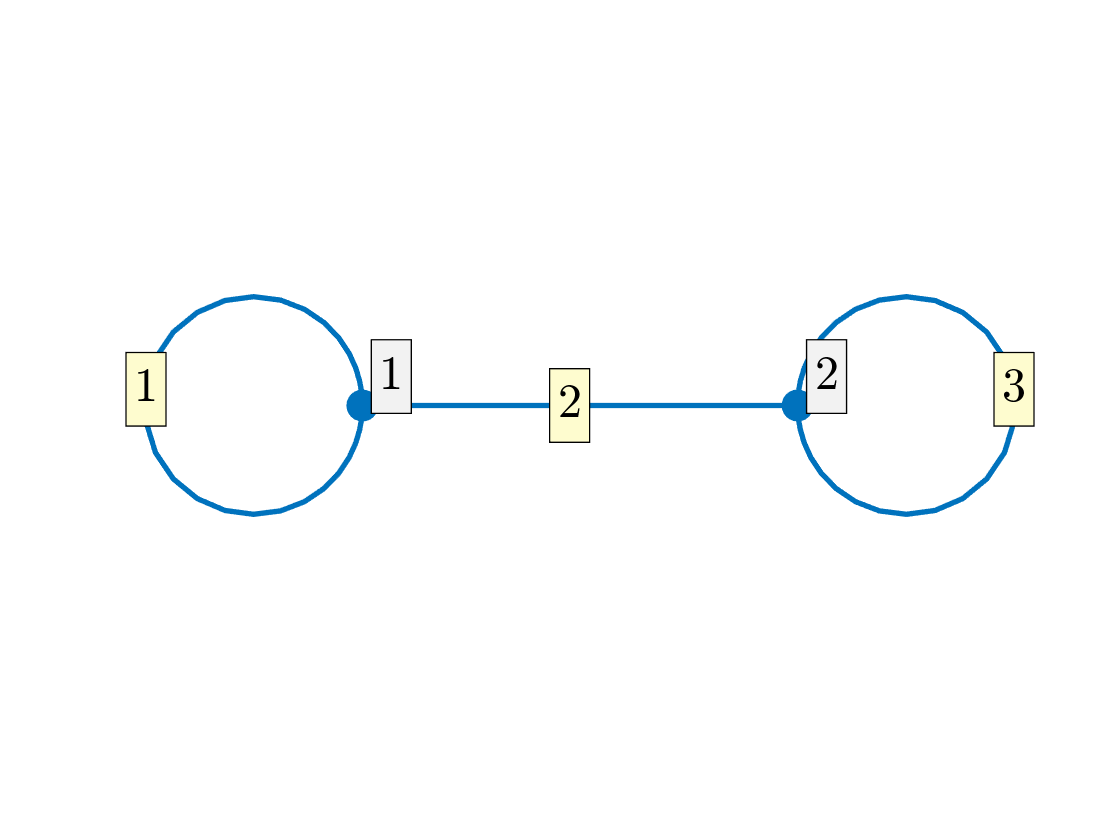

Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nX',16);
Phi.plot('layout')

## Define the function

1 = Heat

2 = Schrodinger

3 = KPP

4  = NLS

type = myMenu('Choose a function','Heat','Linear Schrodinger','KPP','NLS');
f = Phi.myFunc(type);

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used an eigenfunction of the stationary problem as an initial condtion.

[evec,eval] = Phi.eigs(8);
j=4;
lambda = eval(j);
u0 = lambda.*evec(:,j);
tend = 1;
[u,t] = Phi.timeEvolveDAE(f,u0,1e-05,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 1000th data point.

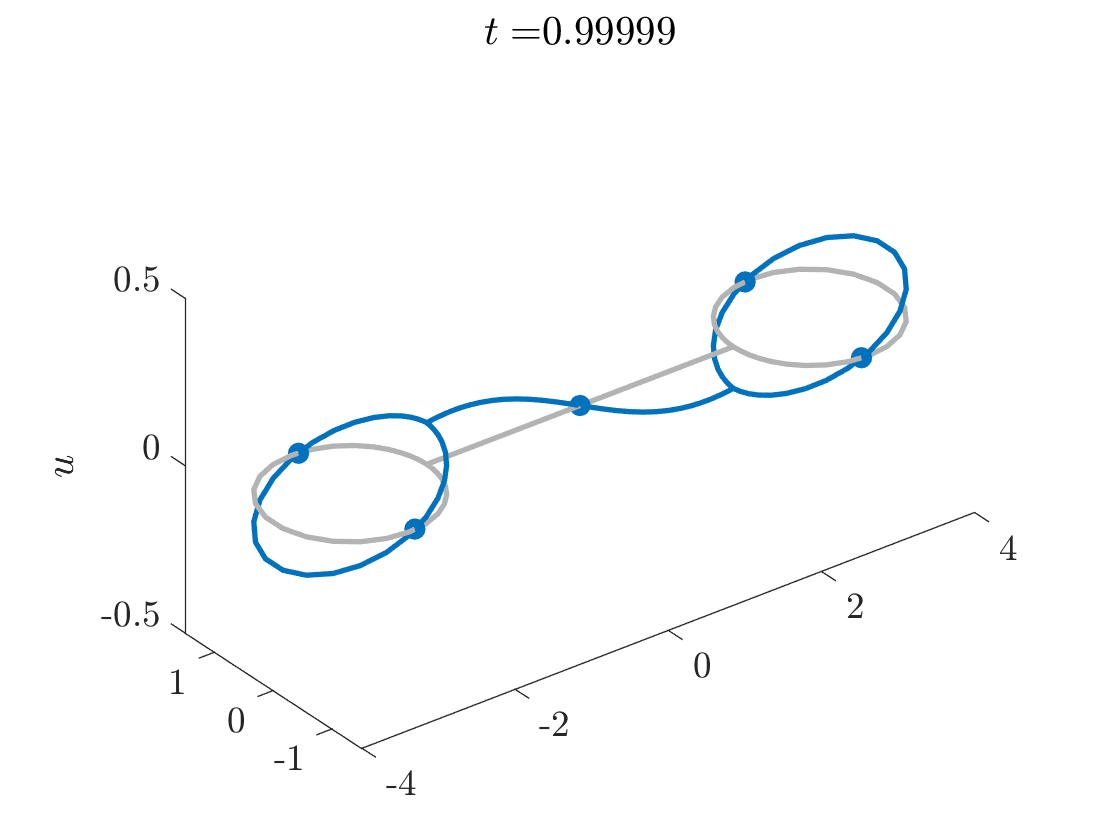

scale = 1000;
for i=1:size(u,2)/scale
    clf
    if type == 1
        Phi.plot(u(:,scale*i))
        axis([-4 4 -1.5 1.5 -.5 .5])
        daspect([1 1 .25])
        title(['$t=$',num2str(t(scale*i))])
        zlabel('$u$')
    else
        Phi.plot(abs(u(:,scale*i)).^2)
        axis([-4 4 -1.5 1.5 -0.05 0.15])
        daspect([1 1 .05])
        title(['$t=$',num2str(t(scale*i))])
        zlabel('$u^2$')
    end
    pause(.0000000001)
end

## Error Analysis

We use an analytical solution to 

if type == 1
    uana = @(t) exp(lambda*t).*u0;
else
    uana = @(t) exp(1i*lambda*t).*u0;
end
error = zeros(1,size(u,2));

for i=1:size(u,2)/scale
    error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
end

disp('The error is:')

The error is:


disp(abs(max(error)))

   3.2561e-12

